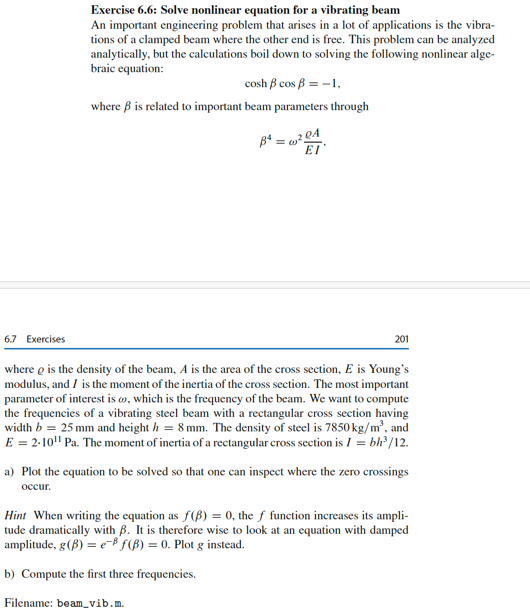

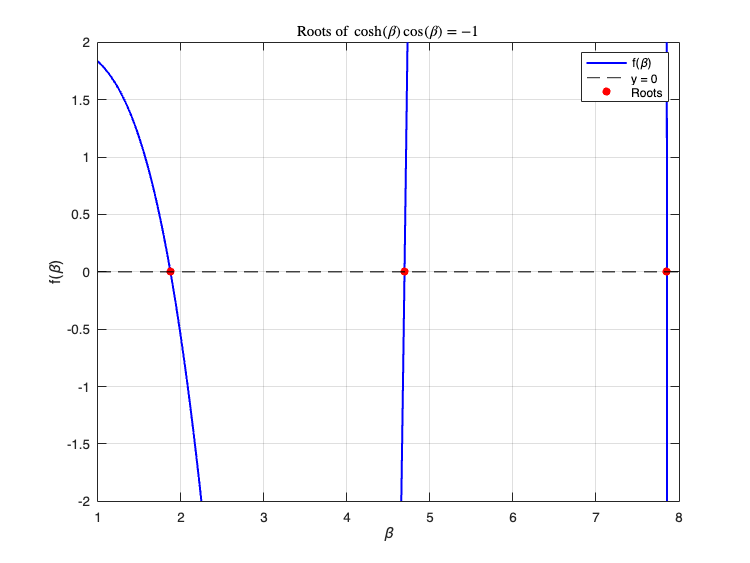

%given parameters
rho = 7850; %density (kg/m^3)
b = 0.025; %width (m)
h = 0.008; %height (m)
A = b * h; %cross-section (m^2)
E = 2e11; %Young's modulus (Pa)
I = (b * h^3) / 12; %moment of inertia (m^4)

%define function and derivative
f = @(beta) cosh(beta) .* cos(beta) + 1;
df = @(beta) sinh(beta) .* cos(beta) - cosh(beta) .* sin(beta);



%plot the function to visualize roots
beta_range = linspace(1, 10, 1000);
f_values = arrayfun(f, beta_range);
figure;
plot(beta_range, f_values, 'b', 'LineWidth', 1.5);
hold on;
yline(0, 'k--', 'LineWidth', 1); % Line at y = 0
scatter(beta_roots, zeros(size(beta_roots)), 'ro', 'filled'); % Roots
xlabel('\beta');
ylabel('f(\beta)');
title('Roots of $\cosh(\beta)\cos(\beta) = -1$', 'Interpreter', 'latex');
legend('f(\beta)', 'y = 0', 'Roots');
grid on;
ylim([-2, 2]);



%devfine initial guesses for roots
initial_guesses = [1.5, 4.5, 7.5];
beta_roots = zeros(size(initial_guesses));

%parameters
pars = struct('eps', 1e-6, 'imax', 25, 'all_x_values', false, 'print', false);

%solve for roots using Newton's method
for i = 1:length(initial_guesses)
    beta_roots(i) = Newton(f, df, initial_guesses(i), pars);
end

%calculate frequencies
frequencies = beta_roots.^2 .* sqrt((E * I) / (rho * A));

%display results
fprintf('Root (beta) and corresponding frequencies:\n');

Root (beta) and corresponding frequencies:


for i = 1:length(beta_roots)
    fprintf('Beta_%d = %.6f, Frequency (omega_%d) = %.6f rad/s\n', ...
        i, beta_roots(i), i, frequencies(i));
end

Beta_1 = 1.875104, Frequency (omega_1) = 40.985505 rad/s
Beta_2 = 4.694091, Frequency (omega_2) = 256.851773 rad/s
Beta_3 = 7.854757, Frequency (omega_3) = 719.192401 rad/s
